
clear; clc;

N = 400; nTrials = 1000; trialLen = 100;
%% Initializing the Network properties

noise_window = 100; % in seconds
baseFolder = fullfile(pwd, 'Data', "N" + num2str(N));
net = IzhikevichNetwork(N, 'heterogeneity', true, 'g_ee', 0.5, 'g_ei', 2, 'g_ie', 2, 'ExtoExDegree', 20, 'InhtoExDegree', 5, 'ExtoInhDegree', 5, 'baseFolder', baseFolder);

net.STDP = true;
net.noise = false;

net.sampling_rate = 5000;


n_mems = 5;
for i=1:n_mems

    stim = Stimulation(net, 100, 2, 30, 50, 5);
    net.stimulation = true;
    net.stims = [stim];
    net.run(100000);

    net.stimulation = false;
    net.STDP = false;
    net.noise = true;
    net.run(noise_window*1000);
    net.STDP = true;
    net.noise = false;
end



data = net.getData();
firings = data.firings;


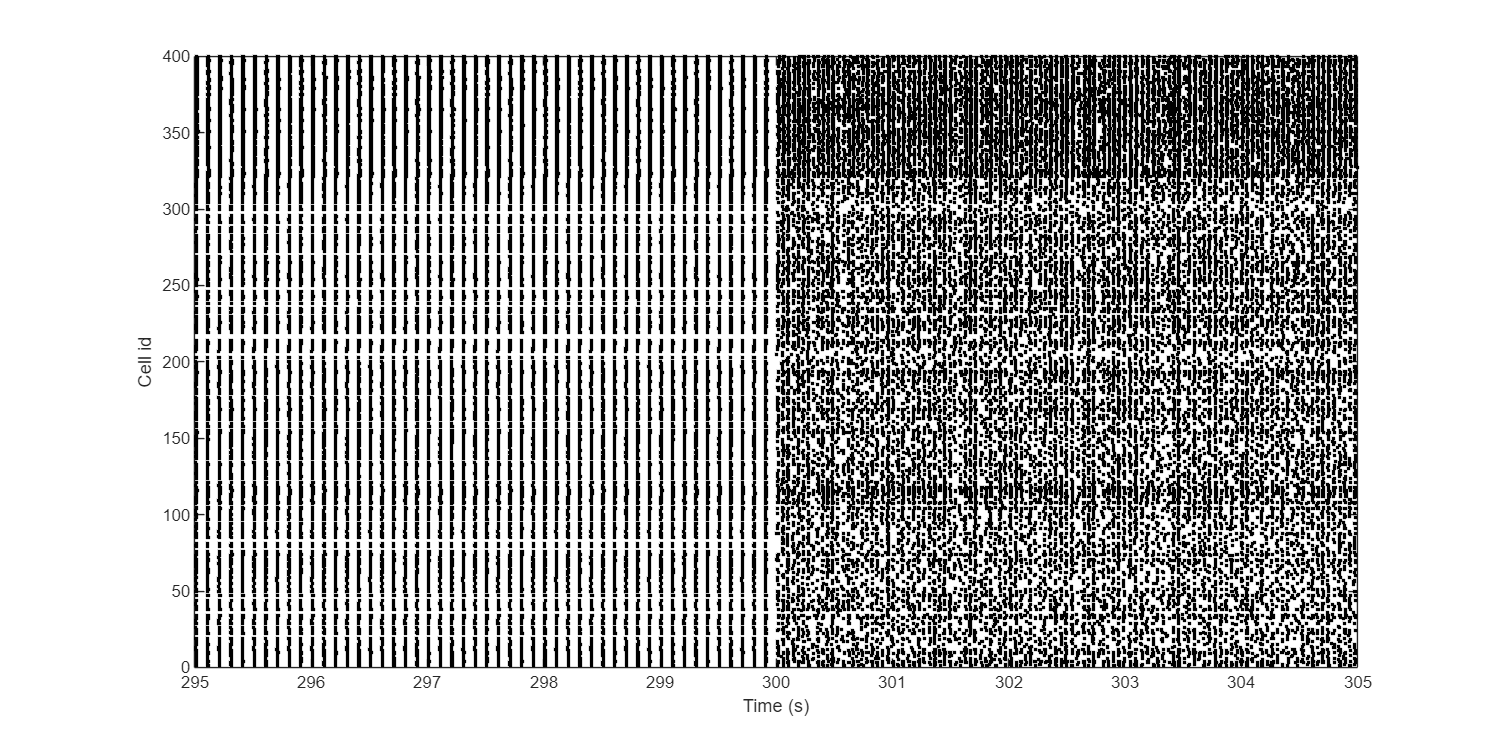

figure(Position=[0, 0, 1200, 600]);
index = (firings(1, :) < 305000) & (firings(1, :) > 295000);
% index = (firings(1, :) < 220000);
plot(firings(1, index)/1000, firings(2, index), 'k.')
xlabel("Time (s)"); ylabel("Cell id")

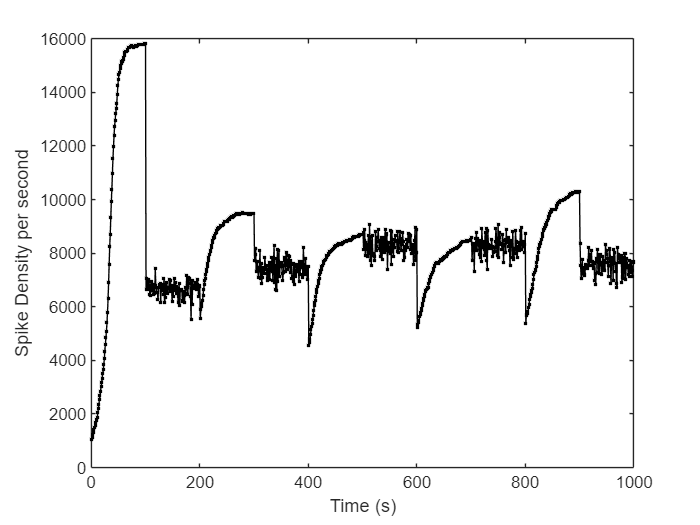


figure; plot(histcounts(firings(1, :), 1000), 'k.-'); 
ylabel("Spike Density per second"); xlabel("Time (s)");

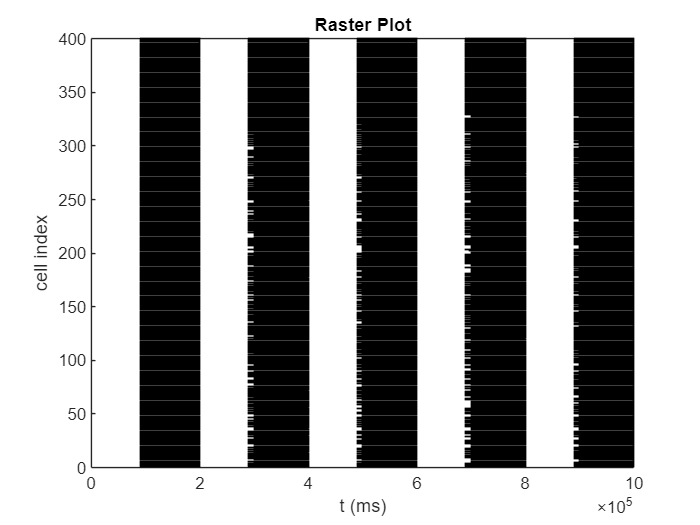

step = 100000 + noise_window*1000;

f = containers.Map();
for i = 1:n_mems
    index1 = (firings(1, :) > step*(i-1)+ 90000 ) & (firings(1, :) < step*(i-1)+100000);
    index2 = (firings(1, :) > step*(i-1)+100000 ) & (firings(1, :) < step*(i-1) + step);
    f(['mem', num2str(i)]) = firings(:, index1);
    f(['noise', num2str(i)]) = firings(:, index2);

end

figure();
ff = cell2mat(f.values());
plot(ff(1, :), ff(2, :), 'k.', MarkerSize=1)
xlabel("t (ms)")
ylabel("cell index")
title("Raster Plot")

Detected bursts (start, end) in ms:
   1.0e+04 *

    9.0004    9.0019
    9.0106    9.0121
    9.0205    9.0220
    9.0307    9.0319
    9.0406    9.0421
    9.0505    9.0520
    9.0607    9.0619
    9.0706    9.0721
    9.0805    9.0820
    9.0907    9.0919
    9.1006    9.1021
    9.1105    9.1120
    9.1207    9.1219
    9.1306    9.1321
    9.1405    9.1420
    9.1507    9.1519
    9.1606    9.1621
    9.1705    9.1720
    9.1807    9.1819
    9.1906    9.1921
    9.2005    9.2020
    9.2107    9.2119
    9.2206    9.2221
    9.2305    9.2320
    9.2407    9.2419
    9.2506    9.2521
    9.2605    9.2620
    9.2707    9.2719
    9.2806    9.2821
    9.2905    9.2920
    9.3007    9.3019
    9.3106    9.3121
    9.3205    9.3220
    9.3307    9.3319
    9.3406    9.3421
    9.3505    9.3520
    9.3607    9.3619
    9.3706    9.3721
    9.3805    9.3820
    9.3907    9.3919
    9.4006    9.4021
    9.4105    9.4120
    9.4207    9.4219
    9.4306    9.4321
    9.4405    9.4420
    9

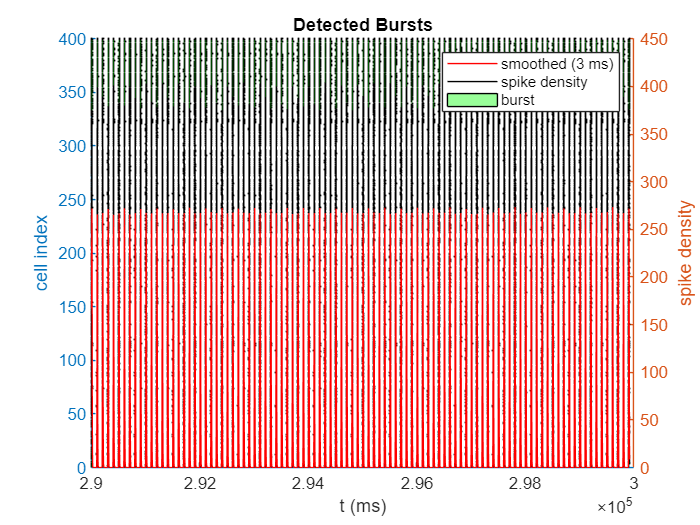

Detected bursts (start, end) in ms:
   1.0e+05 *

    2.9000    2.9002
    2.9010    2.9012
    2.9021    2.9022
    2.9030    2.9032
    2.9040    2.9042
    2.9051    2.9052
    2.9060    2.9062
    2.9070    2.9072
    2.9081    2.9082
    2.9090    2.9092
    2.9100    2.9102
    2.9111    2.9112
    2.9120    2.9122
    2.9130    2.9132
    2.9141    2.9142
    2.9150    2.9152
    2.9160    2.9162
    2.9171    2.9172
    2.9180    2.9182
    2.9190    2.9192
    2.9201    2.9202
    2.9210    2.9212
    2.9220    2.9222
    2.9231    2.9232
    2.9240    2.9242
    2.9250    2.9252
    2.9261    2.9262
    2.9270    2.9272
    2.9280    2.9282
    2.9291    2.9292
    2.9300    2.9302
    2.9310    2.9312
    2.9321    2.9322
    2.9330    2.9332
    2.9340    2.9342
    2.9351    2.9352
    2.9360    2.9362
    2.9370    2.9372
    2.9381    2.9382
    2.9390    2.9392
    2.9400    2.9402
    2.9411    2.9412
    2.9420    2.9422
    2.9430    2.9432
    2.9441    2.9442
    2

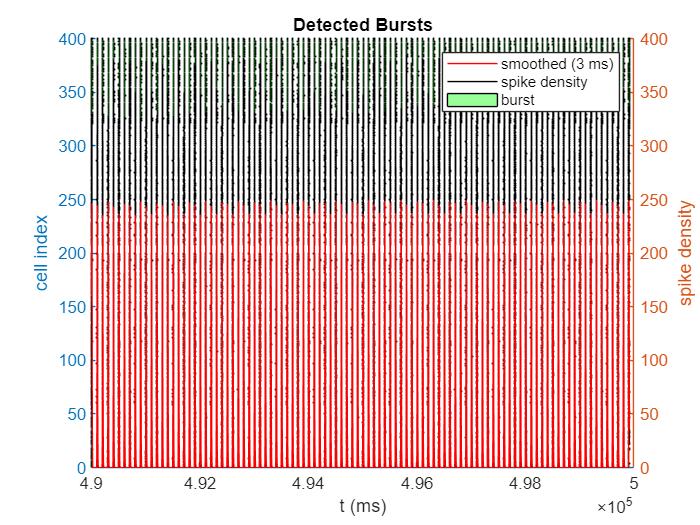

Detected bursts (start, end) in ms:
   1.0e+05 *

    4.9000    4.9002
    4.9010    4.9012
    4.9021    4.9022
    4.9030    4.9032
    4.9040    4.9042
    4.9051    4.9052
    4.9060    4.9062
    4.9070    4.9072
    4.9081    4.9082
    4.9090    4.9092
    4.9100    4.9102
    4.9111    4.9112
    4.9120    4.9122
    4.9130    4.9132
    4.9141    4.9142
    4.9150    4.9152
    4.9160    4.9162
    4.9171    4.9172
    4.9180    4.9182
    4.9190    4.9192
    4.9201    4.9202
    4.9210    4.9212
    4.9220    4.9222
    4.9231    4.9232
    4.9240    4.9242
    4.9250    4.9252
    4.9261    4.9262
    4.9270    4.9272
    4.9280    4.9282
    4.9291    4.9292
    4.9300    4.9302
    4.9310    4.9312
    4.9321    4.9322
    4.9330    4.9332
    4.9340    4.9342
    4.9351    4.9352
    4.9360    4.9362
    4.9370    4.9372
    4.9381    4.9382
    4.9390    4.9392
    4.9400    4.9402
    4.9411    4.9412
    4.9420    4.9422
    4.9430    4.9432
    4.9441    4.9442
    4

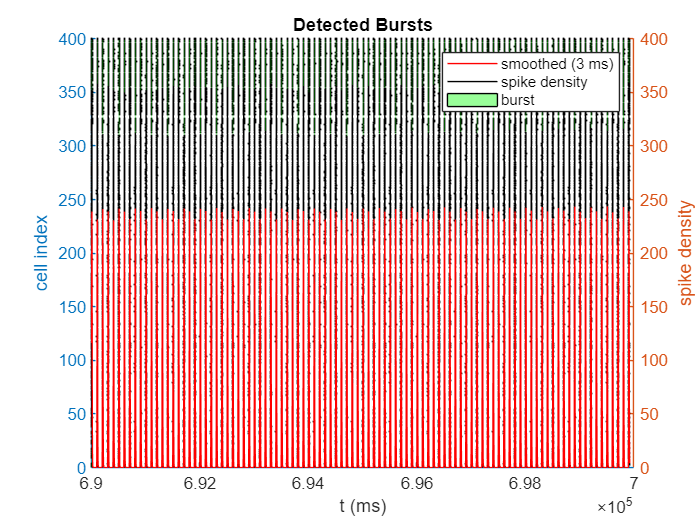

Detected bursts (start, end) in ms:
   1.0e+05 *

    6.9000    6.9002
    6.9011    6.9012
    6.9021    6.9022
    6.9030    6.9032
    6.9041    6.9042
    6.9051    6.9052
    6.9060    6.9062
    6.9071    6.9072
    6.9081    6.9082
    6.9090    6.9092
    6.9101    6.9102
    6.9111    6.9112
    6.9120    6.9122
    6.9131    6.9132
    6.9141    6.9142
    6.9150    6.9152
    6.9161    6.9162
    6.9171    6.9172
    6.9180    6.9182
    6.9191    6.9192
    6.9201    6.9202
    6.9210    6.9212
    6.9221    6.9222
    6.9231    6.9232
    6.9240    6.9242
    6.9251    6.9252
    6.9261    6.9262
    6.9270    6.9272
    6.9281    6.9282
    6.9291    6.9292
    6.9300    6.9302
    6.9311    6.9312
    6.9321    6.9322
    6.9330    6.9332
    6.9341    6.9342
    6.9351    6.9352
    6.9360    6.9362
    6.9371    6.9372
    6.9381    6.9382
    6.9390    6.9392
    6.9401    6.9402
    6.9411    6.9412
    6.9420    6.9422
    6.9431    6.9432
    6.9441    6.9442
    6

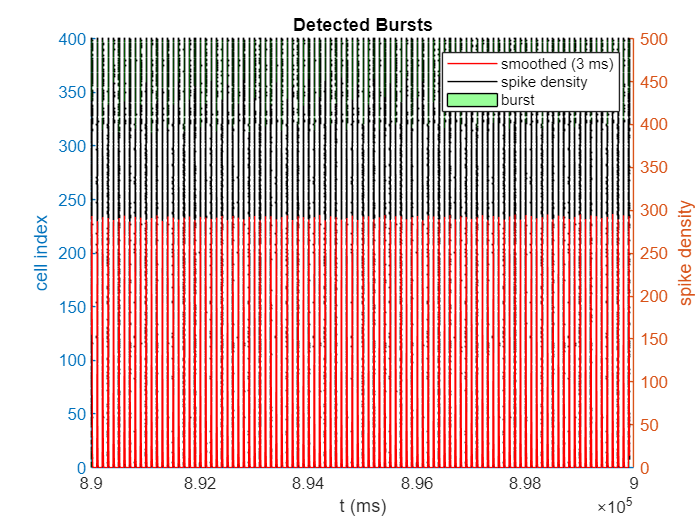

Detected bursts (start, end) in ms:
   1.0e+05 *

    8.9000    8.9002
    8.9011    8.9012
    8.9021    8.9022
    8.9030    8.9032
    8.9041    8.9042
    8.9051    8.9052
    8.9060    8.9062
    8.9071    8.9072
    8.9081    8.9082
    8.9090    8.9092
    8.9101    8.9102
    8.9111    8.9112
    8.9120    8.9122
    8.9131    8.9132
    8.9141    8.9142
    8.9150    8.9152
    8.9161    8.9162
    8.9171    8.9172
    8.9180    8.9182
    8.9191    8.9192
    8.9201    8.9202
    8.9210    8.9212
    8.9221    8.9222
    8.9231    8.9232
    8.9240    8.9242
    8.9251    8.9252
    8.9261    8.9262
    8.9270    8.9272
    8.9281    8.9282
    8.9291    8.9292
    8.9300    8.9302
    8.9311    8.9312
    8.9321    8.9322
    8.9330    8.9332
    8.9341    8.9342
    8.9351    8.9352
    8.9360    8.9362
    8.9371    8.9372
    8.9381    8.9382
    8.9390    8.9392
    8.9401    8.9402
    8.9411    8.9412
    8.9420    8.9422
    8.9431    8.9432
    8.9441    8.9442
    8

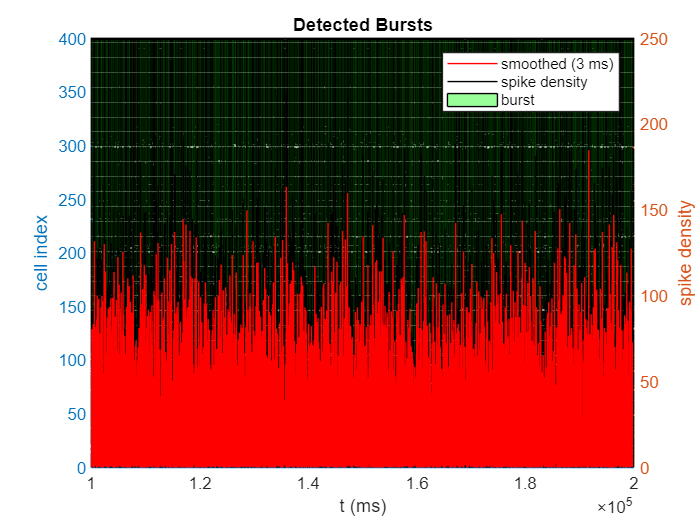

Detected bursts (start, end) in ms:
   1.0e+05 *

    1.0002    1.0003
    1.0006    1.0007
    1.0010    1.0011
    1.0014    1.0016
    1.0019    1.0020
    1.0023    1.0024
    1.0028    1.0029
    1.0032    1.0033
    1.0036    1.0038
    1.0041    1.0042
    1.0048    1.0050
    1.0052    1.0054
    1.0057    1.0058
    1.0074    1.0076
    1.0079    1.0080
    1.0083    1.0084
    1.0087    1.0088
    1.0092    1.0093
    1.0096    1.0097
    1.0100    1.0102
    1.0105    1.0106
    1.0109    1.0111
    1.0114    1.0115
    1.0118    1.0119
    1.0122    1.0123
    1.0126    1.0128
    1.0131    1.0132
    1.0135    1.0137
    1.0141    1.0142
    1.0144    1.0146
    1.0149    1.0150
    1.0153    1.0155
    1.0161    1.0162
    1.0165    1.0166
    1.0170    1.0171
    1.0174    1.0175
    1.0178    1.0180
    1.0183    1.0184
    1.0187    1.0188
    1.0192    1.0193
    1.0196    1.0197
    1.0201    1.0201
    1.0208    1.0209
    1.0213    1.0214
    1.0222    1.0223
    1

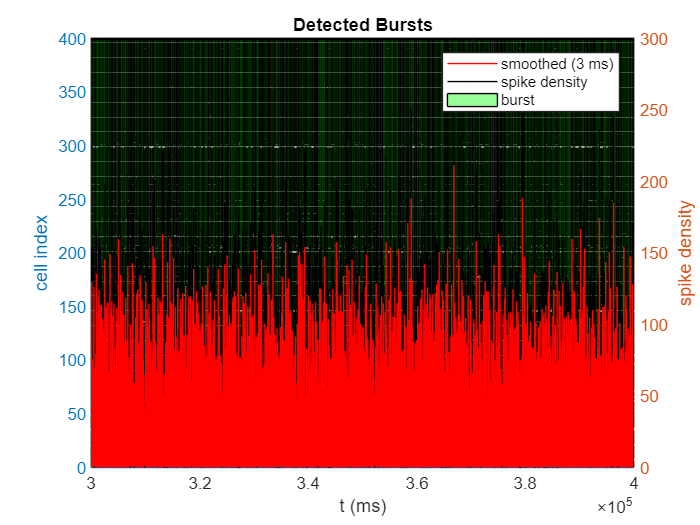

Detected bursts (start, end) in ms:
   1.0e+05 *

    3.0001    3.0003
    3.0005    3.0007
    3.0010    3.0011
    3.0015    3.0016
    3.0019    3.0020
    3.0023    3.0024
    3.0027    3.0028
    3.0036    3.0037
    3.0040    3.0041
    3.0044    3.0045
    3.0048    3.0049
    3.0053    3.0053
    3.0062    3.0063
    3.0066    3.0067
    3.0070    3.0071
    3.0074    3.0075
    3.0078    3.0079
    3.0082    3.0084
    3.0087    3.0088
    3.0091    3.0092
    3.0096    3.0097
    3.0100    3.0101
    3.0105    3.0106
    3.0109    3.0110
    3.0114    3.0115
    3.0118    3.0119
    3.0122    3.0124
    3.0127    3.0128
    3.0132    3.0133
    3.0136    3.0137
    3.0140    3.0141
    3.0144    3.0146
    3.0149    3.0151
    3.0158    3.0159
    3.0163    3.0164
    3.0166    3.0168
    3.0171    3.0172
    3.0176    3.0177
    3.0181    3.0181
    3.0184    3.0185
    3.0188    3.0189
    3.0192    3.0194
    3.0197    3.0198
    3.0201    3.0203
    3.0206    3.0207
    3

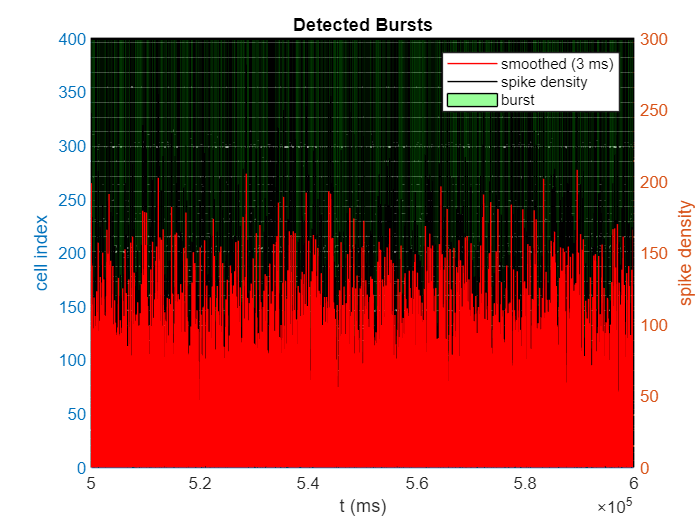

Detected bursts (start, end) in ms:
   1.0e+05 *

    5.0001    5.0003
    5.0006    5.0007
    5.0010    5.0011
    5.0014    5.0015
    5.0019    5.0021
    5.0024    5.0025
    5.0029    5.0030
    5.0033    5.0034
    5.0037    5.0039
    5.0042    5.0043
    5.0047    5.0048
    5.0051    5.0053
    5.0056    5.0057
    5.0060    5.0061
    5.0065    5.0066
    5.0069    5.0070
    5.0073    5.0075
    5.0078    5.0079
    5.0083    5.0084
    5.0087    5.0088
    5.0091    5.0093
    5.0096    5.0097
    5.0100    5.0102
    5.0109    5.0110
    5.0114    5.0115
    5.0118    5.0119
    5.0126    5.0128
    5.0131    5.0132
    5.0141    5.0142
    5.0150    5.0151
    5.0154    5.0155
    5.0159    5.0160
    5.0164    5.0165
    5.0168    5.0169
    5.0178    5.0179
    5.0182    5.0183
    5.0186    5.0188
    5.0191    5.0192
    5.0195    5.0197
    5.0200    5.0201
    5.0205    5.0206
    5.0210    5.0211
    5.0224    5.0225
    5.0228    5.0229
    5.0232    5.0233
    5

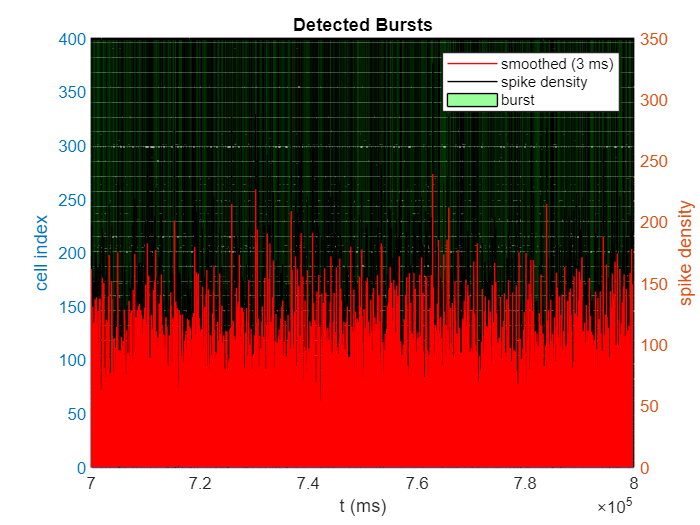

Detected bursts (start, end) in ms:
   1.0e+05 *

    7.0001    7.0003
    7.0006    7.0007
    7.0011    7.0012
    7.0016    7.0017
    7.0025    7.0026
    7.0029    7.0030
    7.0033    7.0034
    7.0037    7.0039
    7.0042    7.0043
    7.0046    7.0047
    7.0051    7.0052
    7.0056    7.0057
    7.0060    7.0062
    7.0065    7.0066
    7.0069    7.0071
    7.0074    7.0075
    7.0078    7.0079
    7.0091    7.0092
    7.0095    7.0097
    7.0101    7.0101
    7.0109    7.0110
    7.0113    7.0114
    7.0118    7.0119
    7.0122    7.0124
    7.0127    7.0128
    7.0132    7.0133
    7.0136    7.0138
    7.0141    7.0142
    7.0146    7.0147
    7.0150    7.0152
    7.0160    7.0161
    7.0164    7.0165
    7.0173    7.0174
    7.0188    7.0189
    7.0192    7.0192
    7.0195    7.0197
    7.0200    7.0201
    7.0204    7.0205
    7.0209    7.0211
    7.0215    7.0216
    7.0220    7.0221
    7.0225    7.0225
    7.0229    7.0230
    7.0233    7.0235
    7.0238    7.0239
    7

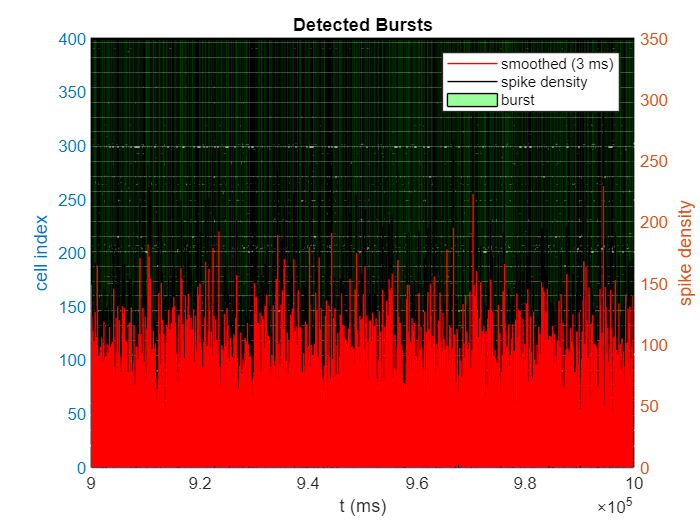

Detected bursts (start, end) in ms:
   1.0e+05 *

    9.0001    9.0003
    9.0006    9.0008
    9.0011    9.0012
    9.0015    9.0017
    9.0028    9.0029
    9.0032    9.0033
    9.0036    9.0038
    9.0041    9.0042
    9.0044    9.0046
    9.0049    9.0050
    9.0054    9.0055
    9.0058    9.0060
    9.0063    9.0064
    9.0068    9.0069
    9.0072    9.0073
    9.0077    9.0078
    9.0082    9.0083
    9.0086    9.0087
    9.0090    9.0091
    9.0095    9.0096
    9.0099    9.0100
    9.0103    9.0105
    9.0108    9.0109
    9.0112    9.0114
    9.0117    9.0118
    9.0122    9.0123
    9.0126    9.0128
    9.0131    9.0132
    9.0135    9.0137
    9.0140    9.0141
    9.0144    9.0146
    9.0154    9.0155
    9.0158    9.0159
    9.0163    9.0165
    9.0168    9.0169
    9.0171    9.0173
    9.0176    9.0177
    9.0181    9.0182
    9.0186    9.0187
    9.0190    9.0191
    9.0194    9.0195
    9.0199    9.0200
    9.0203    9.0204
    9.0207    9.0208
    9.0213    9.0213
    9

bursts = [];
num_burst = containers.Map(f.keys, f.values);
key_list = f.keys;
for key = key_list
    [bursts_temp, fig] = BurstDetector(f(key{1}), [], true, 'All', 3, 3);
    
    bursts = [bursts; bursts_temp];
    num_burst(key{1}) = size(bursts_temp, 1);
end

% f = f(:, f(2, :) <= 320);
[features, f_names] = ExtractBurstFeatures(cell2mat(f.values()), bursts);

Burst Features (First Spike Times, Mean-Subtracted and NaN-Imputed):
    Neuron 1 First Spike Time    Neuron 2 First Spike Time    Neuron 3 First Spike Time    Neuron 4 First Spike Time    Neuron 5 First Spike Time    Neuron 6 First Spike Time    Neuron 7 First Spike Time    Neuron 8 First Spike Time    Neuron 9 First Spike Time    Neuron 10 First Spike Time    Neuron 11 First Spike Time    Neuron 12 First Spike Time    Neuron 13 First Spike Time    Neuron 14 First Spike Time    Neuron 15 First Spike Time    Neuron 16 First Spike Time    Neuron 17 First Spike Time    Neuron 18 First Spike Time    Neuron 19 First Spike Time    Neuron 20 First Spike Time


assemblies = features;
X_mean = nanmean(assemblies, 2);  
X_std = nanstd(assemblies, 0, 2); 

assemblies = (assemblies - X_mean) ./ X_std;

% assemblies = [assemblies(100, :); assemblies(200, :); assemblies(300, :); assemblies(301:end, :)];
% dist = squareform(pdist(assemblies, 'correlation'));
f = waitbar(0, "Please wait");
dist = zeros(size(assemblies, 1), size(assemblies, 1));
for i = 1:size(dist,1)
    waitbar((i-1)/size(dist, 1), f, "Please wait")
    for j = i:size(dist,2)
        idx = ~isnan(assemblies(i, :)) & ~isnan(assemblies(j, :));
        if sum(idx) > 50
            dist(i, j) = corr(assemblies(i, idx)', assemblies(j, idx)');
            dist(j, i) = dist(i, j);
        end
    end
end
close(f)

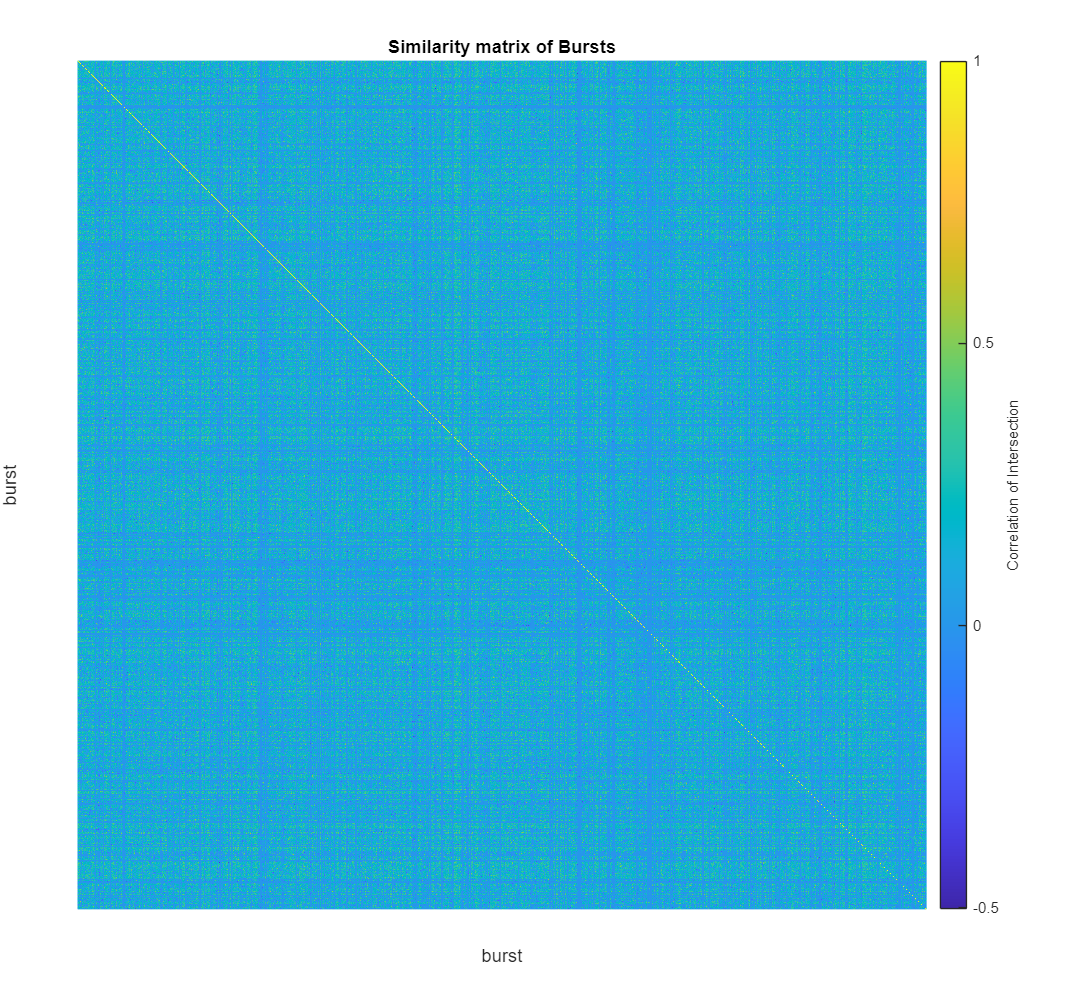

fig = figure(); fig.Position(3:4) = [800, 800]; 
imshow(dist);
colormap('parula');
cb = colorbar();
clim([min(dist, [], 'all'), max(dist, [], 'all')])
xlabel('burst'); ylabel('burst'); cb.Label.String = "Correlation of Intersection";
title("Similarity matrix of Bursts")
saveas(fig, ['Plots' filesep 'image3.png'])

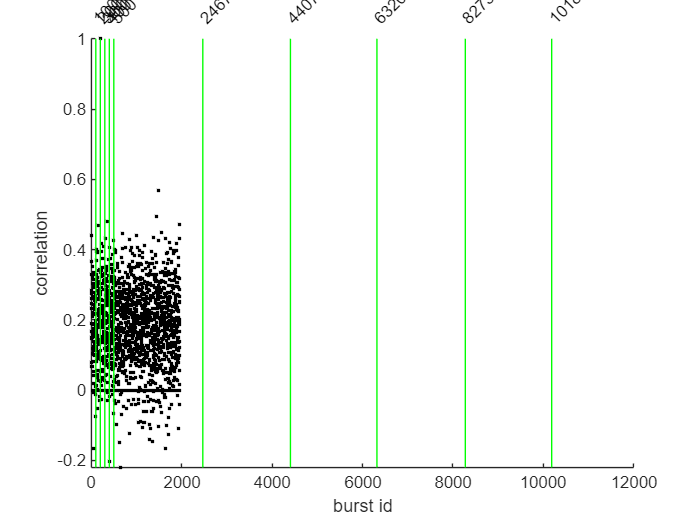


fig = figure(); hold on;
data = dist(200, (n_mems+1):end);
plot(data, 'k.')
counter= 0;
l = num_burst.values;
for b = l(1:end)
    counter = counter + b{1};
    plot(counter*[1, 1], [min(data), max(data)], 'g-')
    text(counter, 1.05*max(data), num2str(counter), "Rotation",45)
    % boxplot(assemblies)
end
ylim([min(data), max(data)])
xlabel("burst id")
ylabel("correlation")
saveas(fig, ['Plots' filesep 'image4.png'])


index = [];
n = 0;
for num = num_burst.values
    index = [index; [n + 1, num{1} + n]];
    n = num{1} + n;
end

Error using horzcat
Dimensions of arrays being concatenated are not consistent.


% Initialize data as a cell array
data = cell(n_mems, n_mems);  
c_label = {};  % Category labels
g_label = {};  % Group labels

% Populate data and labels
for mem = 1:n_mems
    for i = 1:n_mems
        % Extract data for each (mem, i) combination
        temp = dist((mem - 1) * 100 + (1:100), index(i+n_mems, 1):index(i+n_mems, 2));
        
        % Store data in the cell array
        data{i, mem} = temp(:)';  % Ensure each group data is a row vector

        % Define labels
        if mem == 1
            c_label{i} = ['noisy bursts ', num2str(i)];
        end
        g_label{mem} = ['mem', num2str(mem)];
    end
end

% Call the function
fig = figure();
plotGroupedBox(data, c_label, g_label);
saveas(fig, ['Plots' filesep 'image5.png'])


function plotGroupedBox(data, category_labels, group_labels)
    % plotGroupedBox: Creates a box plot with closely grouped boxes for each category,
    % with distinct colors for each group and a legend.
    % 
    % Parameters:
    %   data - Cell array where each cell contains data for each group within categories.
    %          Each cell represents one group (a vector) for each category.
    %   category_labels - Cell array of strings for main categories
    %   group_labels - Cell array of strings for sub-group labels within each category

    % Check the dimensions of data and labels
    num_categories = length(category_labels);
    num_groups = length(group_labels);
    
    % Combine data into one vector and prepare grouping indices
    all_data = [];          % Concatenate all data
    positions = [];         % Custom x-axis positions
    categories = [];        % Main category grouping variable
    groups = [];            % Sub-group within each category

    % Define spacing for box positions
    offset = 0.1;           % Distance between boxes in the same category
    base_pos = 1;           % Starting position for the first category
    position_counter = base_pos;
    
    % Define colors for each group
    colors = lines(num_groups); % Use default MATLAB colormap 'lines' for distinct colors
    
    for c = 1:num_categories
        for g = 1:num_groups
            % Concatenate data for each group within each category
            group_data = data{c, g};
            all_data = [all_data; group_data(:)]; % Add group data
            
            % Set category and group labels for this group
            categories = [categories; repmat(c, length(group_data), 1)];
            groups = [groups; repmat(g, length(group_data), 1)];
            
            % Define x-axis position for each box plot group
            positions = [positions, position_counter + (g - (num_groups + 1) / 2) * offset];
        end
        % Increment position for the next category
        position_counter = position_counter + 1;
    end

    % Generate the box plot with custom positions
    h = boxplot(all_data, {categories, groups}, 'positions', positions, 'Labels', repmat(group_labels, 1, num_categories), 'Whisker', 2.5);

    % Set color for each group box
    for g = 1:num_groups
        set(h(:, g:num_groups:end), 'Color', colors(g, :));  % Apply color to each group
    end

    % Customize the x-axis to label only the main categories
    xticks(base_pos:num_categories);           % Place ticks at category centers
    xticklabels(category_labels);               % Assign labels to main categories
    xlabel('Noisy Bursts after Learning Memory m');
    ylabel('Correlation');
    title('Similarity of Noisy Bursts with Different Memories');

    % Add legend
    hold on;
    for g = 1:num_groups
        plot(NaN, NaN, 'Color', colors(g, :), 'LineWidth', 2);  % Dummy plots for legend colors
    end
    hold off;
    legend(group_labels, 'Location', 'bestoutside');
end




% [~, clusters, ~] = DimensionalityReductionPCA(features, 2, true, 4, f_names);
% figure; hold on;
% plot(clusters, 'ko')
% xlabel("burst id")
% ylabel("cluster id")
% counter = 0;
% 
% for key = num_burst.keys
%     s = key{1};
%     area([counter, counter + num_burst(s)], [4, 4], 'FaceAlpha', 0.3)
%     counter = counter + num_burst(s);
% end

% Select optimal number of clusters (K value) using specified range
fh = @(X,K)(kmeans(X,K,"Distance","cosine"));
eva = evalclusters(features,fh,"CalinskiHarabasz","KList",2:10);
clear fh
K = eva.OptimalK;
clusterIndices = eva.OptimalY;

% Display cluster evaluation criterion values
figure
bar(eva.InspectedK,eva.CriterionValues);
xticks(eva.InspectedK);
xlabel("Number of clusters");
ylabel("Criterion values - calinskiHarabaszCriterion");
legend("Optimal number of clusters is " + num2str(K))
title("Evaluation of Optimal Number of Clusters")
disp("Optimal number of clusters is " + num2str(K));
clear K eva

% Calculate centroids
transformedData = features./sqrt(sum(features.^2,2));
centroids = grpstats(transformedData,clusterIndices,"mean");
clear transformedData

% Display results

% Display 2D scatter plot (PCA)
figure
[~,score] = pca(features);
clusterMeans = grpstats(score,clusterIndices,"mean");
h = gscatter(score(:,1),score(:,2),clusterIndices);
for i2 = 1:numel(h)
    h(i2).DisplayName = strcat("Cluster",h(i2).DisplayName);
end
clear h i2 score
hold on
h = scatter(clusterMeans(:,1),clusterMeans(:,2),50,"kx","LineWidth",2);
hold off
h.DisplayName = "ClusterMeans";
clear h clusterMeans
legend;
title("First 2 PCA Components of Clustered Data");
xlabel("First principal component");
ylabel("Second principal component");